clear; clc; clf; close all;
load('./training-data/filtered_QHD_table.mat')
load('./training-data/filtered_QDP_table.mat')
load('./training-data/deleted_QHD_table.mat')
load('./training-data/deleted_QDP_table.mat')

QH = [filtered_QHD_table.FlowRate_m3h,filtered_QHD_table.Head_m]';
D  = [filtered_QHD_table.Diameter_mm]';

QH_beps=[deleted_QHD_table.FlowRate_m3h,deleted_QHD_table.Head_m]';
D_beps=[deleted_QHD_table.Diameter_mm]';

QD = [filtered_QDP_table.FlowRate_m3h,filtered_QDP_table.Diameter_mm]';
P = [filtered_QDP_table.Power_kW]';

QD_beps=[deleted_QDP_table.FlowRate_m3h,deleted_QDP_table.Diameter_mm]';
P_beps=[deleted_QDP_table.Power_kW]';

randomSeed = 4826;
nn_QHD_size_matrix = [5, 15];
nn_QDH_size_matrix = [5, 15];
nn_QDP_size_matrix = [2, 7, 29, 17];
maxEpochs = 355;
trainFcn = 'trainlm';

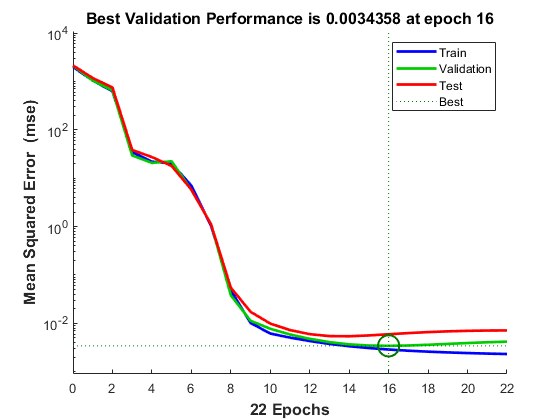

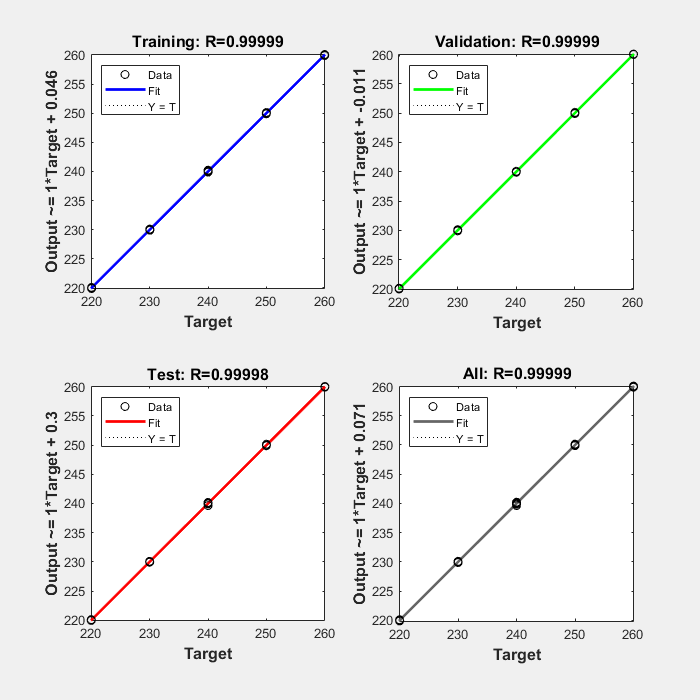

[trainedNetQHD, avgMSEsQHD, trainPerformanceQHD, valPerformanceQHD, testPerformanceQHD] = train_nn(nn_QHD_size_matrix, maxEpochs, trainFcn, QH, D, randomSeed);

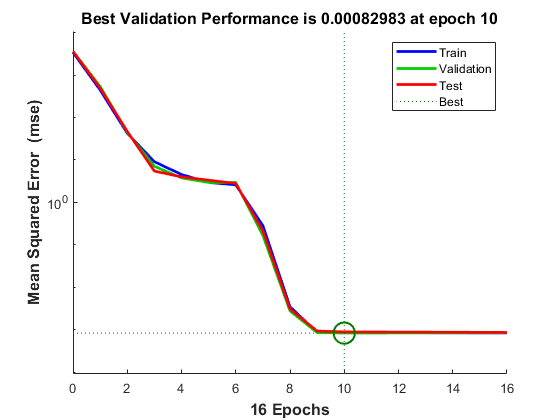

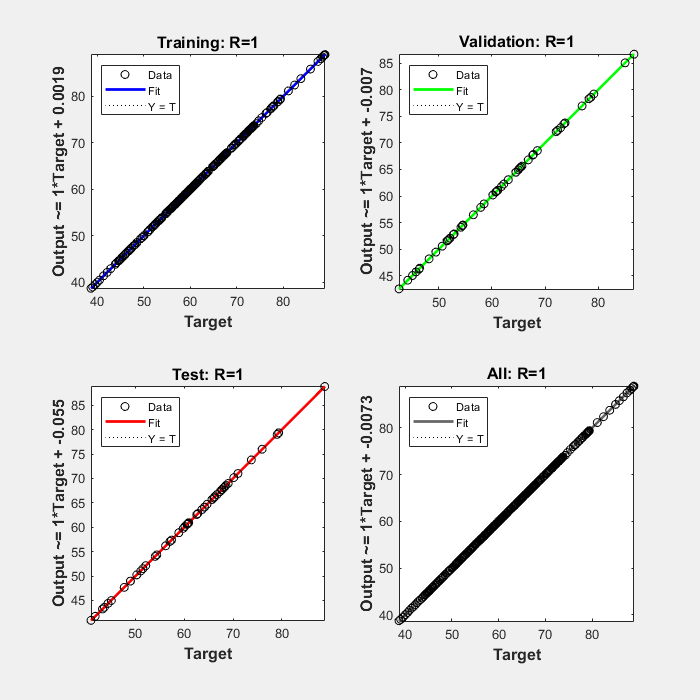

[trainedNetQDH, avgMSEsQDH, trainPerformanceQDH, valPerformanceQDH, testPerformanceQDH] = train_nn(nn_QDH_size_matrix, maxEpochs, trainFcn, [QH(1,:); D], QH(2,:), randomSeed);

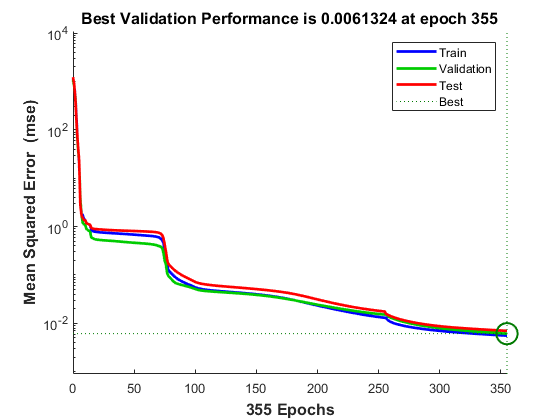

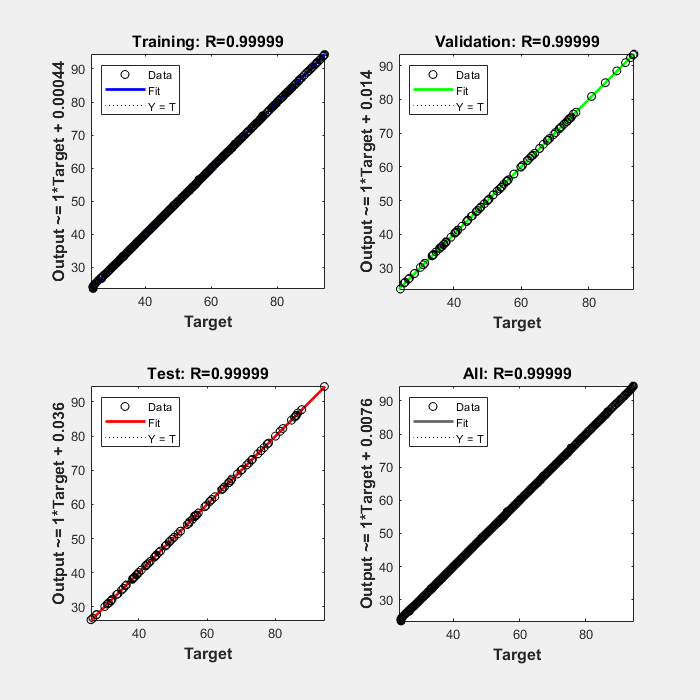

[trainedNetQDP, avgMSEsQDP, trainPerformanceQDP, valPerformanceQDP, testPerformanceQDP] = train_nn(nn_QDP_size_matrix, maxEpochs, trainFcn, QD, P, randomSeed);

function [trainedNet, avgMSEs, trainPerformance, valPerformance, testPerformance] = train_nn(nn_size_matrix, maxEpochs, trainFcn, x, t, randomSeed)
    rng(randomSeed); % Set random seed for reproducibility.
    % Define the neural network.
    net = feedforwardnet(nn_size_matrix, trainFcn);
    % Suppress training GUI for efficiency.
    net.trainParam.showWindow = false;
    net.trainParam.epochs = maxEpochs;

    % Choose a Performance Function
    net.performFcn = 'mse';

    % Choose Input and Output Pre/Post-Processing Functions
    net.input.processFcns = {'removeconstantrows', 'mapminmax'};
    net.output.processFcns = {'removeconstantrows', 'mapminmax'};

    % Define data split for training, validation, and testing.
    % For a list of all data division functions type: help nndivide
    net.divideFcn = 'dividerand';  % Divide data randomly
    net.divideMode = 'sample';  % Divide up every sample
    net.divideParam.trainRatio = 0.7;
    net.divideParam.valRatio = 0.15;
    net.divideParam.testRatio = 0.15;

    % Train the neural network.
    [trainedNet, tr] = train(net, x, t);

    % Evaluate the model performance using mean squared error (MSE).
    predictions = trainedNet(x);
    mse = perform(trainedNet, t, predictions);

    % Recalculate Training, Validation and Test Performance
    trainTargets = t(tr.trainInd);
    valTargets = t(tr.valInd);
    testTargets = t(tr.testInd);
    trainPerformance = perform(trainedNet, trainTargets, predictions(tr.trainInd));
    valPerformance = perform(trainedNet, valTargets, predictions(tr.valInd));
    testPerformance = perform(trainedNet, testTargets, predictions(tr.testInd));

    % Calculate the average MSE
    avgMSEs = (mse + trainPerformance + valPerformance + testPerformance) / 4;

    % Plot the performance plot
    figure;
    plotperform(tr);

    % Plot the regression plots for training, validation, and test sets
    figure;
    plotregression(trainTargets, predictions(tr.trainInd), 'Training', ...
                   valTargets, predictions(tr.valInd), 'Validation', ...
                   testTargets, predictions(tr.testInd), 'Test', ...
                   t, predictions, 'All');

end
